# ELE632 - Lab 3

Gabriel Casciano

500744076

## Part A

#### A1

x = @(n, a, b, A, B) A.*cos(a*pi.*n) + B.*sin(b*pi.*n);

a = 2.4;
b = 3.2;
A = 4;
B = 2;

No = 5

No = 5

OHM = (2*pi)/No

OHM = 1.2566

The fundamental frequency of $x[n] = 4cos(2.4\pi n) + 2 sin(3.2\pi n)$ , $N_0 = 5$ and $\Omega_o= \frac{2 \pi}{N_0}=1.2566$

#### A2

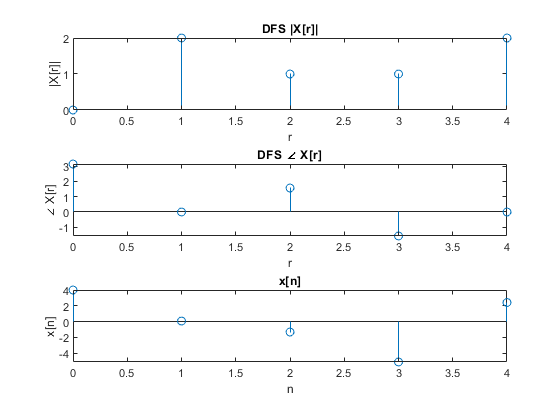

x_1 = @(n) 4.*cos(2.4*pi.*n) + 2*sin(3.2*pi.*n);
n = 0:No-1;

for r = 0:No-1
    X_1(r+1) = sum(x_1(n) .*exp(-j*r*(OHM)*n))/No;
end

r = 0:No-1;
subplot(3,1,1);
stem(r, abs(X_1));
title("DFS |X[r]|");
xlabel("r");
ylabel("|X[r]|")

subplot(3,1,2);
stem(r, angle(X_1));
title("DFS \angle X[r]");
xlabel("r");
ylabel("\angle X[r]")

subplot(3,1,3);
stem(n, x_1(n));
title("x[n]");
xlabel("n");
ylabel("x[n]")

#### A3

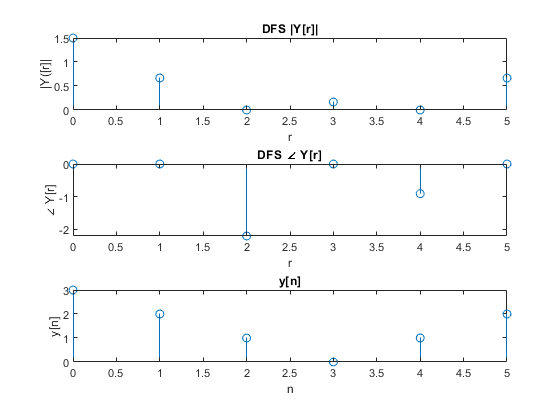

No = 6;
y = [3 2 1 0 1 2];
OHM = (2*pi)/No;
n = 0:No-1;

for r = 0:No-1
    Y(r+1) = sum(y.*exp(-j*r*(OHM)*n))/No;
end


subplot(3,1,1);
stem(n, abs(Y));
title("DFS |Y[r]|");
xlabel("r");
ylabel("|Y([r]|")
subplot(3,1,2);
stem(n, angle(Y));
title("DFS \angle Y[r]");
title("DFS \angle Y[r]");
xlabel("r");
ylabel("\angle Y[r]");
subplot(3,1,3);
stem(n, y);
title("y[n]");
xlabel("n");
ylabel("y[n]");

## Part B

#### B1

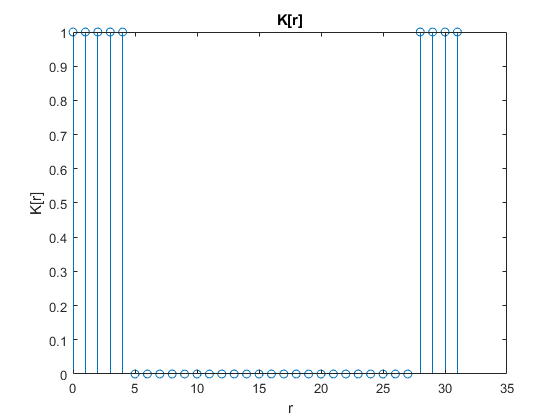

No_2 = 32;
OHM = (2*pi)/No_2;
K = [ones(1,5) zeros(1,23) ones(1,4)];
n = 0:No_2-1;
for r = 0:No_2-1
    k(r+1) = sum(K.*exp(j*(OHM)*r.*n));
end

subplot(1,1,1, 'replace');
stem(n, K(n+1));
title("K[r]");
ylabel("K[r]");
xlabel("r");

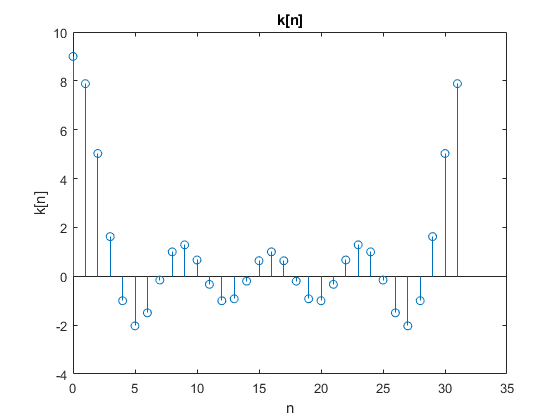

subplot(1,1,1 ,'replace');
stem(n, real(k));
title("k[n]");
ylabel("k[n]");
xlabel("n");

#### B2

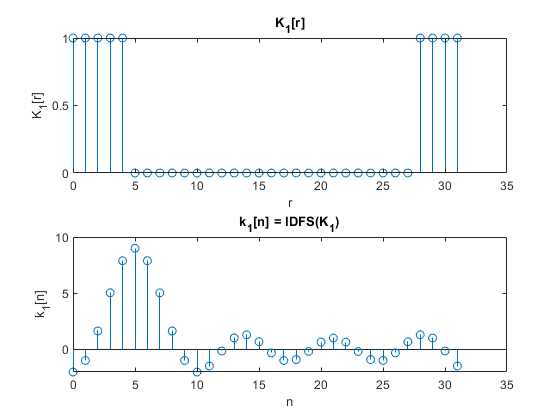

K_1 = K.*exp(-j*5*(OHM).*n);

for r = 0:No_2-1
    k_1(r+1) = sum(K_1.*exp(j*OHM*r.*n));
end

n = 0:No_2-1;

subplot(2,1,1);
stem(n, abs(K_1));
title("K_{1}[r]");
ylabel("K_{1}[r]");
xlabel("r");


subplot(2,1,2);
stem(n, real(k_1));
title("k_{1}[n] = IDFS(K_{1})");
ylabel("k_{1}[n]");
xlabel("n");

The difference between $y[n]$ and $y_1[n]
$ is caused by $Y[r]e^{-j5\Omega_0 r}$ by multiplying by $e^{-j5\Omega_0r}$ there is a time delay, shifted forward by a factor of 5.

## Part C

#### C1

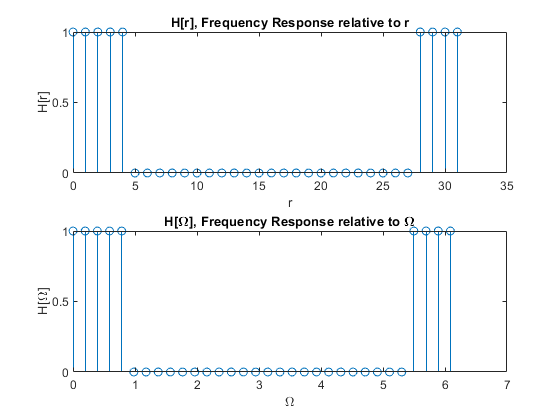

u = @(n) 1*(n>=0);
H = @(n) u(n) - u(n-5) + u(n-28) - u(n-32);

No = 32;
n = 0:No-1;
Omega = (2*pi)/No;

for r = 0:No-1
    h(r+1) = sum(H(r).*exp(j*r*Omega.*n));
end

r = 0:No-1;

subplot(2,1,1);
stem(r,H(r));
title("H[r], Frequency Response relative to r");
ylabel("H[r]");
xlabel("r");

subplot(2,1,2);
stem(r.*Omega,H(r));
title("H[\Omega], Frequency Response relative to \Omega");
ylabel("H[\Omega]");
xlabel("\Omega");

#### C2

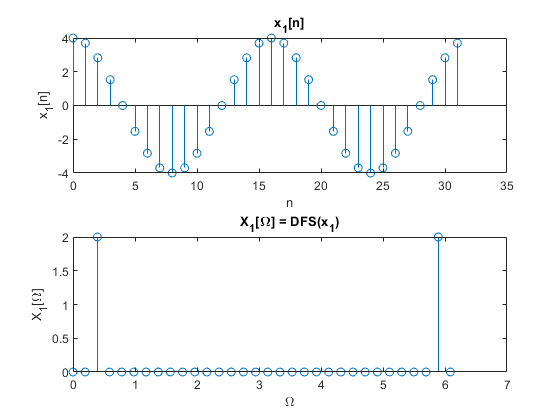

x1 = @(n) 4.*cos((pi*n)/8);

n = 0:No-1;
H2 = H(n);

for r = 0:No-1
    X1(r+1) = sum(x1(n).*exp(-j*r*Omega.*n))/No;
end

Y1 = H2 .* X1;

for r = 0:No-1
    y1(r+1) = sum(Y1.*exp(j*r*Omega.*n));
end

subplot(2,1,1);
stem(n, x1(n));
title("x_{1}[n]");
ylabel("x_{1}[n]");
xlabel("n");

subplot(2,1,2);
stem(n*Omega, abs(X1));
title("X_{1}[\Omega] = DFS(x_{1})");
ylabel("X_{1}[\Omega]");
xlabel("\Omega");

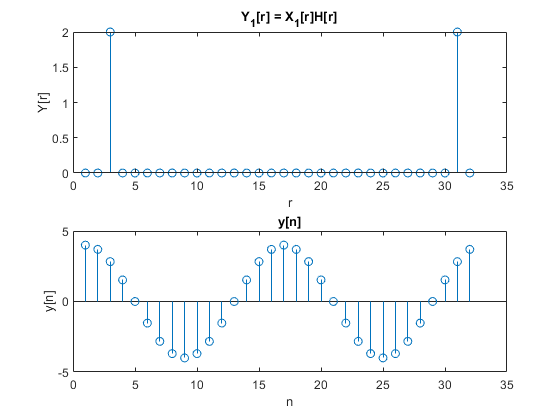

subplot(2,1,1);
stem(abs(Y1));
title("Y_1[r] = X_{1}[r]H[r]");
ylabel("Y[r]");
xlabel("r");

subplot(2,1,2);
stem(real(y1));
title("y[n]");
ylabel("y[n]");
xlabel("n");

#### C3

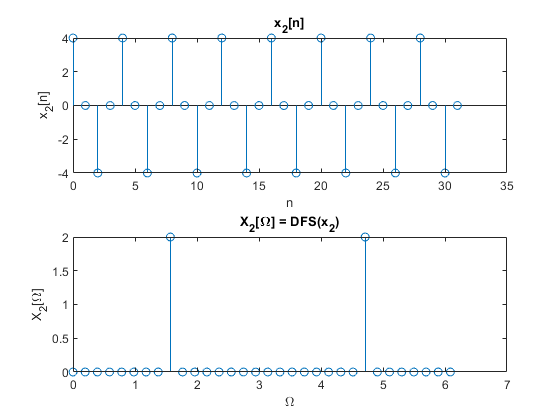

x2 = @(n) 4.*cos((pi*n)/2);

for r = 0:No-1
    X2(r+1) = sum(x2(n).*exp(-j*r*Omega.*n))/No;
end

Y2 = H2 .* X2;

for r = 0:No-1
    y2(r+1) = sum(Y2 .* exp(j*r*Omega.*n));
end

subplot(2,1,1);
stem(n, x2(n));
title("x_{2}[n]");
ylabel("x_{2}[n]");
xlabel("n");

subplot(2,1,2);
stem(n*Omega, abs(X2));
title("X_{2}[\Omega] = DFS(x_{2})");
ylabel("X_{2}[\Omega]");
xlabel("\Omega");

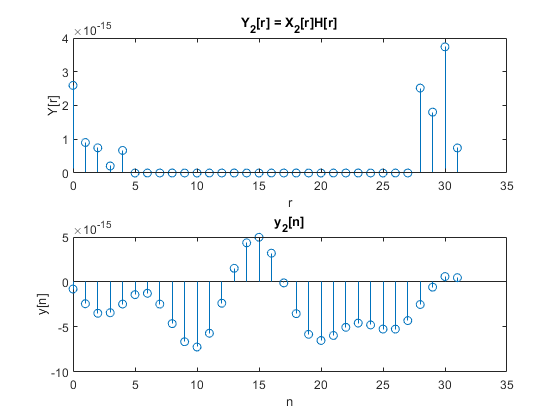

subplot(2,1,1);
stem(n, abs(Y2));
title("Y_2[r] = X_{2}[r]H[r]");
ylabel("Y[r]");
xlabel("r");

subplot(2,1,2);
stem(n, real(y2));
title("y_{2}[n]");
ylabel("y[n]");
xlabel("n");

#### C.4

The most noticable difference is in the spectral components of the frequency response of $Y_1$ and $Y_2$, primarily the additional spetral components in $Y_2$ and that $y_2[n]$ is basically 0. 

If we analyze $H$we notice that it has spectral components on the range $[0,\frac{\pi}{4}],[\frac{7 \pi}{4},2\pi]$. If we compare the spectral components of $X_1$ and $X_2$ we see that for $X_1=\{ D_{\frac{3\pi}{16}}=1 \}$and $X_2=\{ D_{\frac{9\pi}{18}}=1 \}$if we compare the poles of the functions with the poles of the sysyem we can see that $X_1$ falls within the range of $H$ and $X_2$ does not, ths is also visually noticable when compareing the frequency response. 

Thus, we can concluse that this is a band pass filter that operates in the range of: $[0,\frac{\pi}{4}],[\frac{7 \pi}{4},2\pi]$.